% run finResults = xPxRanalysis(numSim, tspan); 
% either in the command window or here. 
finResults = xPxRanalysis(numSim, tspan); 

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.791559 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.303816 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.480665 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.601065 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.479693 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.531563 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.685740 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 13.822528 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



 Plot dependence against homophily

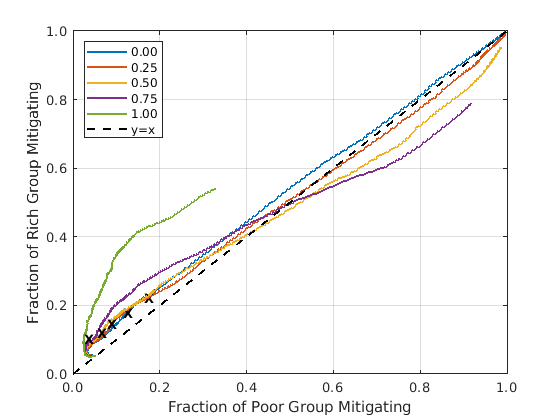

clf
plot(finResults.xPout(1,:),finResults.xRout(1,:),'LineWidth',1.5)
[m,n]=size(finResults.xPout);
text(finResults.xPout(1,431),finResults.xRout(1,431),"X","FontWeight","bold")
hold on;
for idx_=2:1:m
    temp_x = finResults.xPout(idx_,:);
    temp_y = finResults.xRout(idx_,:);
    plot(temp_x, temp_y,'LineWidth',1.5); 
    
    text(temp_x(1,431),temp_y(1,431),"X","FontWeight","bold");
end
plot([0,1],[0,1],'Color','k', 'LineStyle','--','LineWidth',1.5)
yticks(0.0:0.2:1.0)
legend({"0.00","0.25","0.50","0.75","1.00","y=x"}, 'Location', 'northwest')
xlabel("Fraction of Poor Group Mitigating")
ylabel("Fraction of Rich Group Mitigating")

ax=gca; ax.XGrid='on'; ax.YGrid='on';
xtickformat("%,.1f");ytickformat("%,.1f");

Plot dependence against \alpha_{P1}/f_{max}

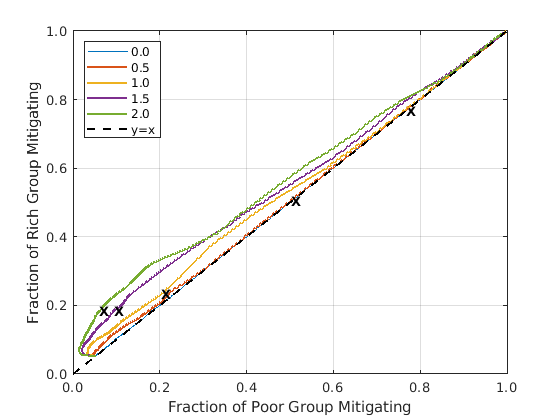

% h=0
clf
plot(finResults.xPout_dis_heq0(1,:),finResults.xRout_dis_heq0(1,:))
[m,n]=size(finResults.xPout_dis_heq0);
text(finResults.xPout_dis_heq0(1,431),finResults.xRout_dis_heq0(1,431),"X","FontWeight","bold")
hold on;
for idx_=2:1:m
    temp_x = finResults.xPout_dis_heq0(idx_,:);
    temp_y = finResults.xRout_dis_heq0(idx_,:);
    plot(temp_x, temp_y,'LineWidth',1.5); 
    
    text(temp_x(1,431),temp_y(1,431),"X","FontWeight","bold");
end
plot([0,1],[0,1],'Color','k', 'LineStyle','--','LineWidth',1.5)
yticks(0.0:0.2:1.0)
legend({"0.0", ...
    "0.5", ...
    "1.0", ...
    "1.5", ...
    "2.0", ...
    "y=x"}, 'Location', 'northwest');
xlabel("Fraction of Poor Group Mitigating")
ylabel("Fraction of Rich Group Mitigating")
%title("h=0.0")
ax=gca; ax.XGrid='on'; ax.YGrid='on';
xtickformat("%,.1f");ytickformat("%,.1f");

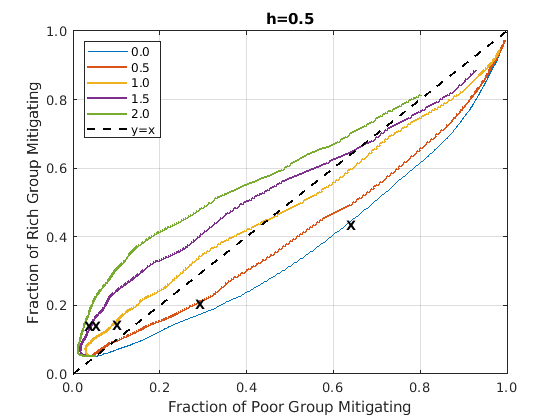

% h= 0.5
clf
plot(finResults.xPout_dis_heq0p5(1,:),finResults.xRout_dis_heq0p5(1,:))
[m,n]=size(finResults.xPout_dis_heq0p5);
text(finResults.xPout_dis_heq0p5(1,431),finResults.xRout_dis_heq0p5(1,431),"X","FontWeight","bold")
hold on;
for idx_=2:1:m
    temp_x = finResults.xPout_dis_heq0p5(idx_,:);
    temp_y = finResults.xRout_dis_heq0p5(idx_,:);
    plot(temp_x, temp_y,'LineWidth',1.5); 
    
    text(temp_x(1,431),temp_y(1,431),"X","FontWeight","bold");
end
plot([0,1],[0,1],'Color','k', 'LineStyle','--','LineWidth',1.5)
yticks(0.0:0.2:1.0)
legend({"0.0","0.5","1.0","1.5","2.0","y=x"}, 'Location', 'northwest')
xlabel("Fraction of Poor Group Mitigating")
ylabel("Fraction of Rich Group Mitigating")
title("h=0.5")
ax=gca; ax.XGrid='on'; ax.YGrid='on';
xtickformat("%,.1f");ytickformat("%,.1f");

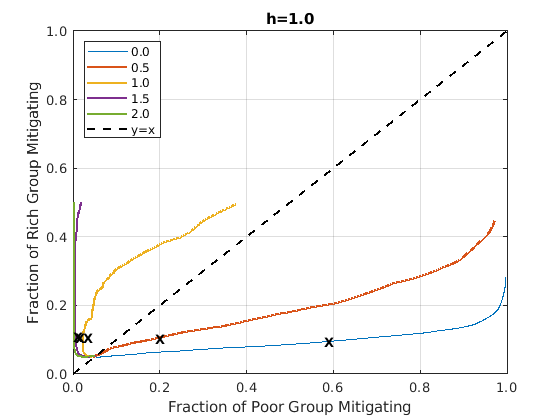

clf
plot(finResults.xPout_dis_heq1(1,:),finResults.xRout_dis_heq1(1,:))
[m,n]=size(finResults.xPout_dis_heq1);
text(finResults.xPout_dis_heq1(1,431),finResults.xRout_dis_heq1(1,431),"X","FontWeight","bold")
hold on;
for idx_=2:1:m
    temp_x = finResults.xPout_dis_heq1(idx_,:);
    temp_y = finResults.xRout_dis_heq1(idx_,:);
    plot(temp_x, temp_y,'LineWidth',1.5); 
    
    text(temp_x(1,431),temp_y(1,431),"X","FontWeight","bold");
end
plot([0,1],[0,1],'Color','k', 'LineStyle','--','LineWidth',1.5)
yticks(0.0:0.2:1.0)
legend({"0.0","0.5","1.0","1.5","2.0","y=x"}, 'Location', 'northwest')
xlabel("Fraction of Poor Group Mitigating")
ylabel("Fraction of Rich Group Mitigating")
title("h=1.0")
ax=gca; ax.XGrid='on'; ax.YGrid='on';

xtickformat("%,.1f");ytickformat("%,.1f");

allResults = simESM_w_soc_YJM(numSim, tspan, 0.5, 5.0);

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.829021 seconds.


pre2014 = allResults.pre2014;

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2200;

% Vary homophily. 
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 15.0);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(:,:);
    xRvals = xRvals(:,:);
    T_ = T_(:,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 21.969303 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.509649 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.124964 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.292059 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.968656 seconds.


clear allResults;
clear xPvals; clear xRvals;

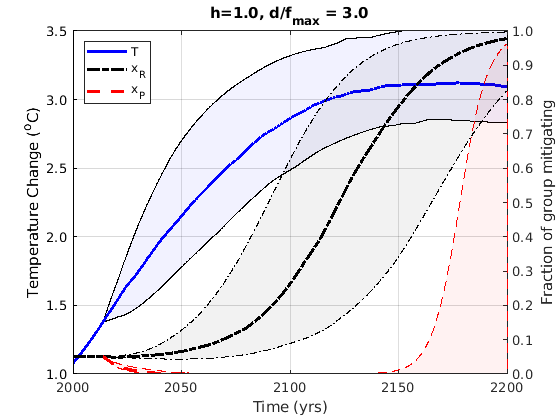



%%%%%%%%%%%%%%
% h=1.0, alpha_P1/f_max = 0.0
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, d/f_{max} = 3.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

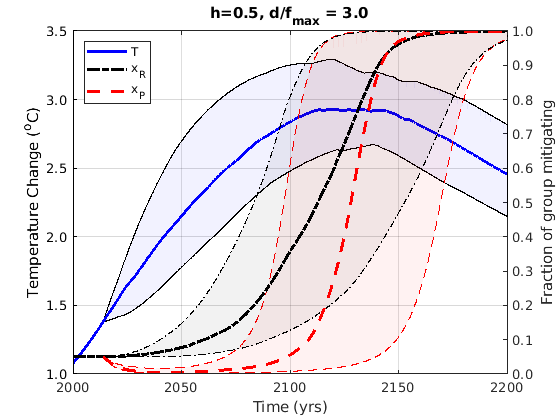

%%%%%%%%%%%%%%
% h=0.5, alpha_P1/f_max = 0.0
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.5, d/f_{max} = 3.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

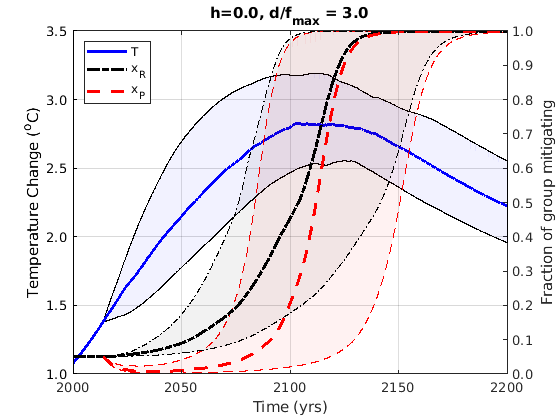

% h=0.0, alpha_P1/f_max = 0.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.0, d/f_{max} = 3.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

%% interaction = 0.5

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2214;

% Vary homophily. 
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 20.0);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(:,:);
    xRvals = xRvals(:,:);
    T_ = T_(:,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 27.587594 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 29.508950 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 29.611051 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 28.536948 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 28.643417 seconds.


clear allResults;
clear xPvals; clear xRvals;

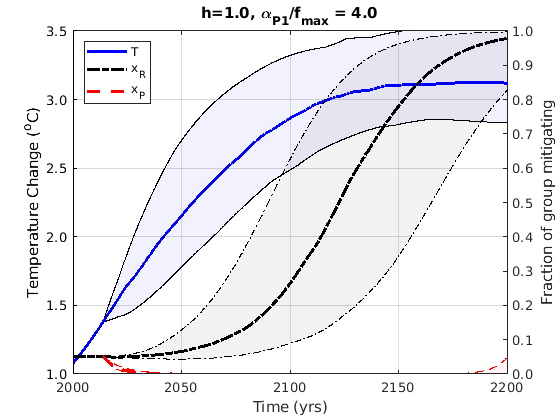



%%%%%%%%%%%%%%
% h=1.0, alpha_P1/f_max = 0.5
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, \alpha_{P1}/f_{max} = 4.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

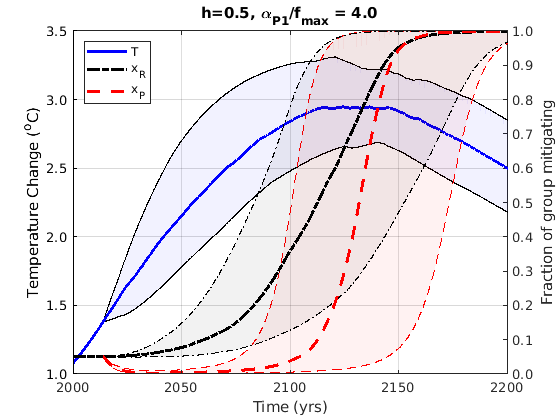

%%%%%%%%%%%%%%
% h=0.5, alpha_P1/f_max = 0.5
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.5, \alpha_{P1}/f_{max} = 4.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

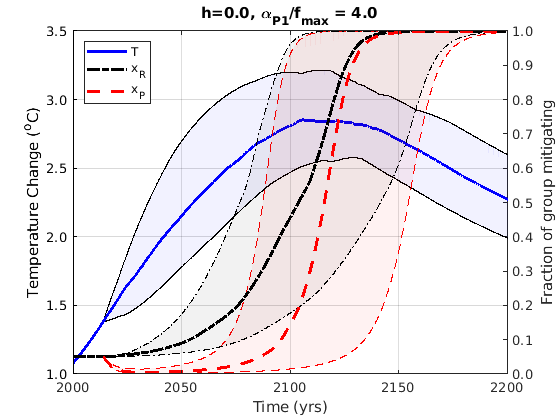

% h=0.0, alpha_P1/f_max = 0.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.0, \alpha_{P1}/f_{max} = 4.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

%%% alpha_P1/fmax = 1.0

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2200;

% Vary homophily. 
[dump_, size_tspan] = size(tspan);
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 5.0);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(1:size_tspan,:);
    xRvals = xRvals(1:size_tspan,:);
    T_ = T_(1:size_tspan,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 24.053569 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 27.227291 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.378280 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.777917 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.923761 seconds.


clear allResults;
clear xPvals; clear xRvals;

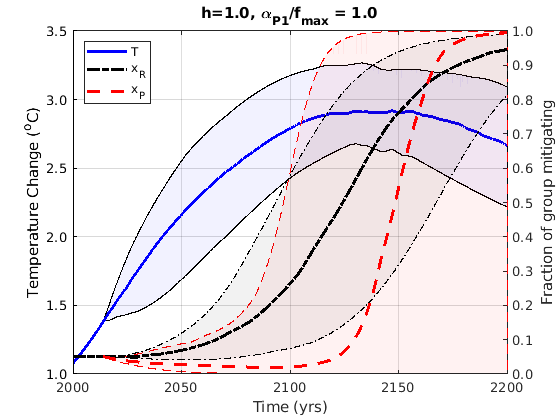

% h=1.0; alpha_P1/f_max= 1.0
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, \alpha_{P1}/f_{max} = 1.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

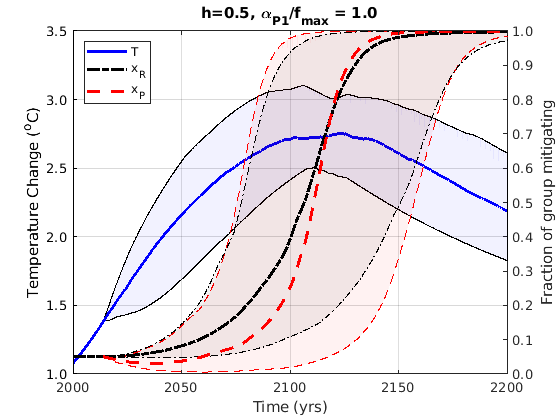

% h=0.5; alpha_P1/f_max= 1.0
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.5, \alpha_{P1}/f_{max} = 1.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

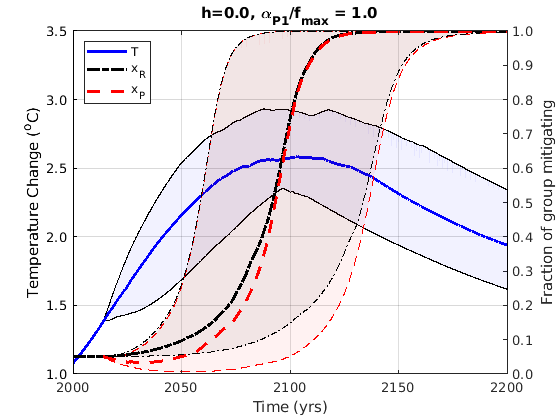


% h=0.0; alpha_P1/f_max= 1.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.0, \alpha_{P1}/f_{max} = 1.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%% alpha_P1/fmax = 2.0

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2200;

% Vary homophily. 
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 10.0);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(:,:);
    xRvals = xRvals(:,:);
    T_ = T_(:,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 26.190861 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.964234 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.525965 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 25.763609 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 24.702948 seconds.


clear allResults;
clear xPvals; clear xRvals;

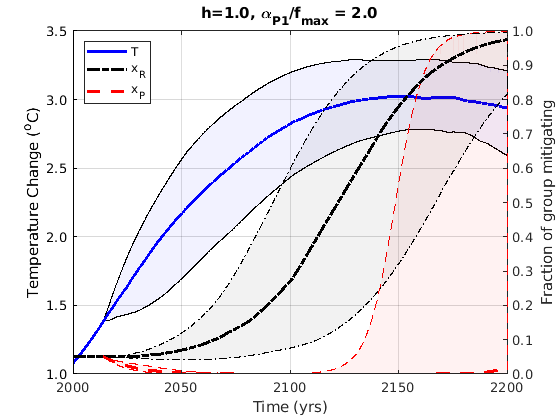

% h=1.0; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, \alpha_{P1}/f_{max} = 2.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

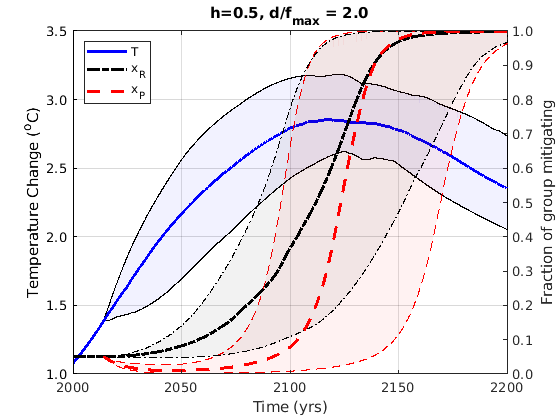

% h=0.5; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.5, d/f_{max} = 2.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

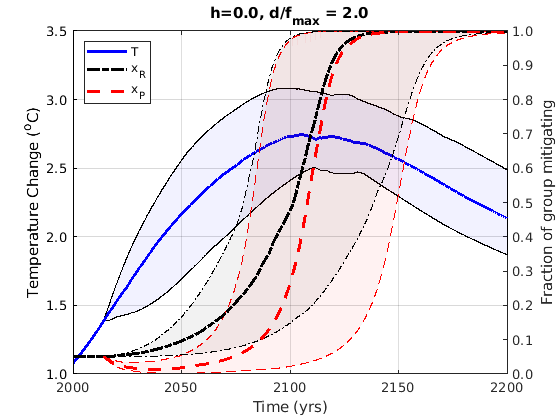


% h=0.0; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.0, d/f_{max} = 2.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

%%% alpha_P1/fmax = 1.5

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2214;

% Vary homophily. 
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 7.5);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(:,:);
    xRvals = xRvals(:,:);
    T_ = T_(:,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 29.880596 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 29.173742 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 28.813819 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 29.786920 seconds.
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

Elapsed time is 33.419119 seconds.


clear allResults;
clear xPvals; clear xRvals;

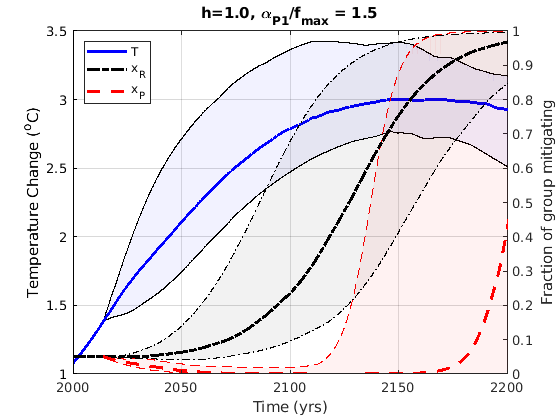

% h=1.0; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, \alpha_{P1}/f_{max} = 1.5")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

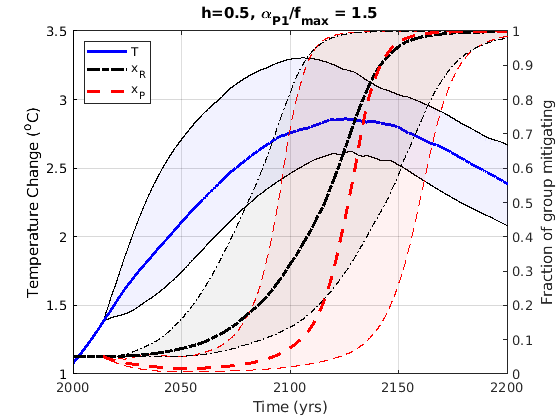

% h=0.5; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
ytickformat('%,.1f')
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.5, \alpha_{P1}/f_{max} = 1.5")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

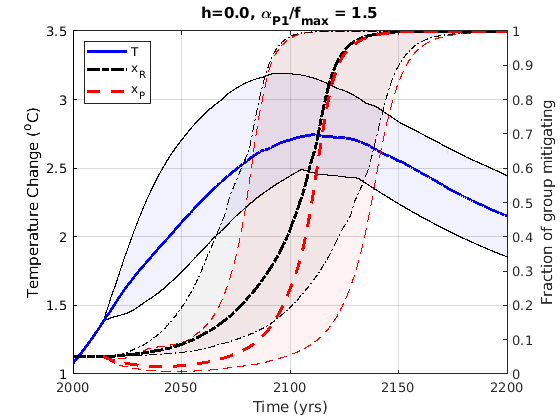


% h=0.0; alpha_P1/f_max= 2.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
yyaxis right
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=0.0, \alpha_{P1}/f_{max} = 1.5")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
ylim([1.0,3.5])

%%% alpha_P1/fmax = 3.0

disp(apple) % just a stopper

Unrecognized function or variable 'apple'.

xPout = [];
lowxPout  = [];
highxPout = [];
UEP_xP = [];
LEP_xP = [];

xRout = [];
lowxRout  = [];
highxRout = [];
UEP_xR = [];
LEP_xR = [];

Tvals = [];
lowTvals = [];
highTvals= [];

numSim=100;tspan=2014:0.1:2214;

% Vary homophily. 
for h_=(0.0:0.25:1.0)
    % run sim to grab xPvals, and xRvals. 
    allResults = simESM_w_soc_YJM(numSim, tspan, h_, 15.0);

    % need to grab xPvals, xRvals, and normalize each sim by the max group size.
    xPvals = allResults.xPvals./(1-allResults.prop_R0);
    xRvals = allResults.xRvals./(allResults.prop_R0);
    
    T_ = allResults.T;
    
    % only want up to time 2100. Since tspan = 2014:0.1:tfinal>2100, it occurs @ index 861
    xPvals = xPvals(:,:);
    xRvals = xRvals(:,:);
    T_ = T_(:,:);

    xPvalsMed = median(xPvals');
    lowxP  = quantile(xPvals',0.05);
    highxP = quantile(xPvals',0.95);
    
    xRvalsMed = median(xRvals');
    lowxR  = quantile(xRvals',0.05);
    highxR = quantile(xRvals',0.95);
    
    T_med = median(T_');
    lowT  = quantile(T_', 0.05);
    highT = quantile(T_', 0.95);

    xPout = [xPout;xPvalsMed];
    lowxPout = [lowxPout;lowxP];
    highxPout = [highxPout;highxP];
    
    xRout = [xRout;xRvalsMed];
    lowxRout = [lowxRout;lowxR];
    highxRout = [highxRout;highxR]; 
    
    Tvals = [Tvals;T_med];
    lowTvals  = [lowTvals; lowT];
    highTvals = [highTvals; highT];
end
clear allResults;
clear xPvals; clear xRvals;

% h=1.0; alpha_P1/f_max= 3.0
clf
[size_, size_T] = size(T_);
idx2use=5;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
yyaxis right
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
title("h=1.0, \alpha_{P1}/f_{max} = 3.0")
xlabel("Time (yrs)");
ax.YColor = [0.15,0.15,0.15];
p_xP_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','red', 'marker','none','LineStyle',"--");
p_xR_bl = plot([2000,2014],[0.05,0.05],'LineWidth', 2.25,'Color','k', 'marker','none','LineStyle',"-.");
yyaxis left
plot(pre2014(:,1), pre2014(:,7),'LineWidth',2.25, 'Color','blue');
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')

% h=0.5; alpha_P1/f_max= 3.0
clf
[size_, size_T] = size(T_);
idx2use=3;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
yyaxis right
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
title("h=0.5, \alpha_{P1}/f_{max} = 3.0")
xlabel("Time (yrs)");


% h=0.0; alpha_P1/f_max= 3.0
clf
[size_, size_T] = size(T_);
idx2use=1;
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highTvals(idx2use,:) fliplr(lowTvals(idx2use,:))], 'b'); alpha(0.05)
hold on
p_T=plot(tspan(:,1:size_), Tvals(idx2use,:),'LineWidth',2.25, 'Color','blue');
ylabel("Temperature Change (^oC)")
yyaxis right
ylim([0,1.0])
ylabel("Fraction of group mitigating")
fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxPout(idx2use,:) fliplr(lowxPout(idx2use,:))], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [tspan(:,1:size_) fliplr(tspan(:,1:size_))],  [highxRout(idx2use,:) fliplr(lowxRout(idx2use,:))],'black', 'LineStyle', '-.'); alpha(0.05)
p_xR=plot(tspan(:,1:size_), xRout(idx2use,:),'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(tspan(:,1:size_), xPout(idx2use,:),'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
%ylabel("Temperature Change (^oC)");
%yyaxis right
%ylabel("Fraction of group mitigating");
%plot(tspan(:,1:861),xRout(5,:), 'LineWidth',1.5,'LineStyle','-.')
%plot(tspan(:,1:861),xPout(5,:), 'LineWidth',1.5)
%legend("T", "xR", "xP",'Location',"northwest")
ax=gca;ax.XGrid='on';ax.YGrid='on';
xlim([2000,2200])
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')
title("h=0.0, \alpha_{P1}/f_{max} = 3.0")
xlabel("Time (yrs)");